# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 4.5.2 and 4.5.3 Backprojection Algorithm - Learjet and Backhoe

% Speed of light
c = 299792458;

% Set the image span (m)
x_span = 10;
y_span = 10;
z_span = 10;

% Number of bins in x, y and z
nx = 50;
ny = 50;
nz = 50;

% Set the dynamic range (dB)
dynamic_range = 40;

% Set the polarization
polarization = 'VV';

% Set the window type
window_type = 'Hamming';

% Set up the image space
x = linspace(-0.5 * x_span, 0.5 * x_span, nx);
y = linspace(-0.5 * y_span, 0.5 * y_span, ny);
z = linspace(-0.5 * z_span, 0.5 * z_span, nz);
[x_image, y_image, z_image] = meshgrid(x, y, z);

% Set the FFT length for this dataset
fft_length = 8192;

% Load the selected target
data = LoadMonostaticSignatureFile('lear_0el_90az_big.sig');
% data = LoadMonostaticSignatureFile('backhoe_15el_90az.sig');

% Select the polarization
switch polarization
    case 'VV'
        signal = data.vv;
    case 'HH'
        signal = data.hh;
    case 'HV'
        signal = data.hv;
end

% Get the sensor azimuth and elevation
sensor_az = deg2rad(data.az + 15);
sensor_el = deg2rad(data.el - 15);  %0, -30, -20
frequency = data.freq;

% Size of the data
nf = length(frequency);
na = length(sensor_az);
ne = length(sensor_el);

% Get the window coefficients
coefficients = ones(nf, ne, na);

switch window_type
    case 'Hanning'
        h1 = hanning(nf);
        h2 = hanning(na);
        h3 = hanning(ne);
        for i = 1:nf
            for j = 1:ne
                for k = 1:na
                    coefficients(i, j, k) = (h1(i) * h2(k) * h3(j)) ^ (1/3);
                end
            end
        end
    case 'Hamming'
        h1 = hamming(nf);
        h2 = hamming(na);
        h3 = hamming(ne);
        for i = 1:nf
            for j = 1:ne
                for k = 1:na
                    coefficients(i, j, k) = (h1(i) * h2(k) * h3(j)) ^ (1/3);
                end
            end
        end
end

% Set up the angular grid
[az_grid, el_grid] = meshgrid(sensor_az, sensor_el);

% Apply the selected window
signal = signal .* coefficients;

% Reconstruct the image
bp_image = backprojection_3d(signal, az_grid, el_grid, x_image, y_image, z_image, frequency, fft_length);

Az = 10 of 321
Az = 20 of 321
Az = 30 of 321
Az = 40 of 321
Az = 50 of 321
Az = 60 of 321
Az = 70 of 321
Az = 80 of 321
Az = 90 of 321
Az = 100 of 321
Az = 110 of 321
Az = 120 of 321
Az = 130 of 321
Az = 140 of 321
Az = 150 of 321
Az = 160 of 321
Az = 170 of 321
Az = 180 of 321
Az = 190 of 321
Az = 200 of 321
Az = 210 of 321
Az = 220 of 321
Az = 230 of 321
Az = 240 of 321
Az = 250 of 321
Az = 260 of 321
Az = 270 of 321
Az = 280 of 321
Az = 290 of 321
Az = 300 of 321
Az = 310 of 321
Az = 320 of 321



clear signal data x y z

% Normalize the image
a = abs(bp_image) ./ max(max(max(abs(bp_image))));


#### Plot the results

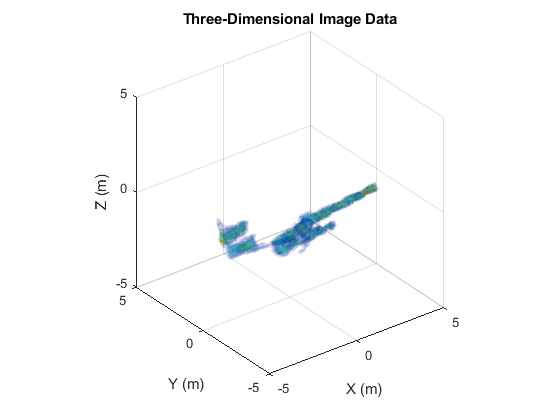

plot_iso(z_image, y_image, x_image, a, 20);
title('Three-Dimensional Image Data')
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')
xlim([-0.5 * x_span, 0.5 * x_span])
ylim([-0.5 * y_span, 0.5 * y_span])
zlim([-0.5, 4])
zlim([-0.5 * z_span, 0.5 * z_span])

#### Plot the upsampled version

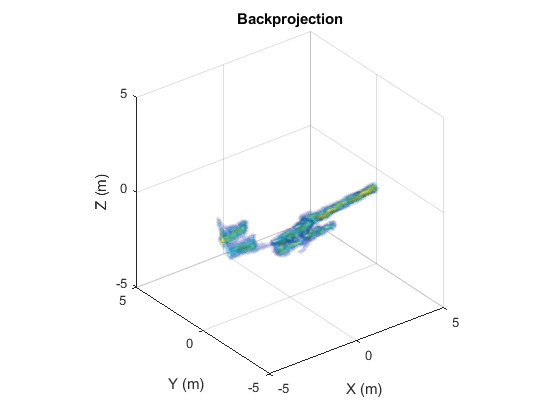

% Upsample desired size
sz = [400, 400, 400];

[x, y, z] = ndgrid(linspace(1,nx,sz(1)), linspace(1,ny,sz(2)), linspace(1,nz,sz(3)));
      
xg = linspace(-0.5*x_span,0.5*x_span,sz(1));
yg = linspace(-0.5*y_span,0.5*y_span,sz(2));
zg = linspace(-0.5*z_span,0.5*z_span,sz(3));

ai = interp3(a, x, y, z);

ai = permute(ai,[2 3 1]);

plot_iso(xg, yg, zg, ai, 20); 
title('Backprojection')
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')
xlim([-0.5 * x_span, 0.5 * x_span])
ylim([-0.5 * y_span, 0.5 * y_span])
zlim([-0.5 * z_span, 0.5 * z_span])